# Kmeans

clc; % clean command propmt
clear; % clean exist varaibles
close all; % close all figures.

**Kmeans with 2D data**

The built-in 'fisherisis' dataset is used in this practice. 

It contains data on the sepal length, sepal width, petal length, and petal width of the plant.

% Load fisheriris
data = importdata("fisheriris.mat")

data = 다음 필드를 포함한 struct :
    species: {150×1 cell}
       meas: [150×4 double]


% Plot the data without labeling
X = data.meas(:,3:4);   % feature : petal length, petal width

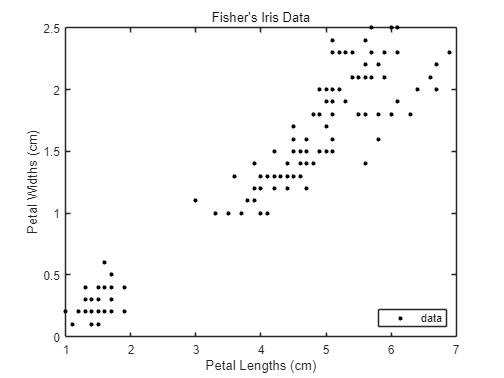

figure(1)
plot(X(:,1),X(:,2),'k.','MarkerSize',10);
title('Fisher''s Iris Data');
xlabel('Petal Lengths (cm)');
ylabel('Petal Widths (cm)');
legend('data','Location','southeast');

**K-means Clustering**

rng(2);         % Fix randomness for reproducibility
k = 3;          % Number of cluster
[C_num,C_mean] = kmeans(X,k)    % [assigned cluster, centroid]

C_num =      2
     2
     2
     2
     2
     2
     2
     2
     2
     2


C_mean =     4.2926    1.3593
    1.4620    0.2460
    5.6261    2.0478


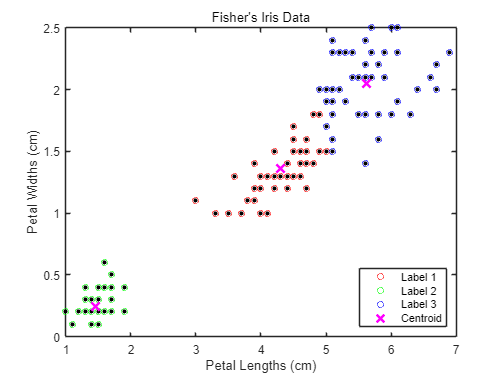

% Plot the clustered data
figure(1); hold on;
plot(X(C_num==1,1),X(C_num==1,2),'ro','MarkerSize',5) 
plot(X(C_num==2,1),X(C_num==2,2),'go','MarkerSize',5)
plot(X(C_num==3,1),X(C_num==3,2),'bo','MarkerSize',5)
plot(C_mean(:,1),C_mean(:,2),'mx','MarkerSize',10,'LineWidth',2)
title('Fisher''s Iris Data');
xlabel('Petal Lengths (cm)'); 
ylabel('Petal Widths (cm)');
legend('','Label 1', 'Label 2', 'Label 3', 'Centroid','location','southeast')

**Accuracy**

% Generate the label vector
% Label 1 is for versicolor, label 2 is for setosa, label 3 is for virginica
y = zeros(length(data.species),1);
y(ismember(data.species,'versicolor')) = 1;
y(ismember(data.species,'setosa')) = 2;
y(ismember(data.species,'virginica')) = 3;

% Calculate the correct classification
acc = num2str(round(sum(y == C_num)/length(y)*100,2));
disp(['The classification accuracy is ' num2str(acc) '%'])

The classification accuracy is 94.67%


**K-means with 3D data**

clc; % clean command propmt
clear; % clean exist varaibles
close all; % close all figures

**Make Random Data**

X = rand(1000, 3);  % 1000 samples with 3 features

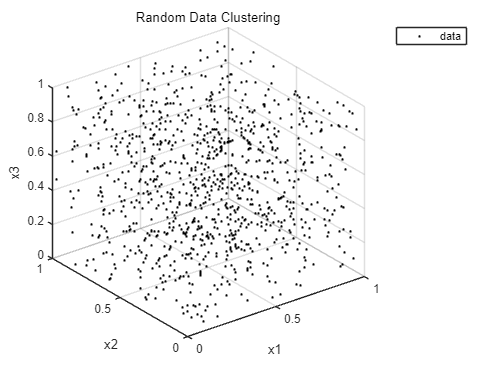

% Plot the random data
figure
scatter3(X(:,1), X(:,2), X(:,3),'k.'); 
legend('data')
title('Random Data Clustering');
xlabel('x1'); 
ylabel('x2');
zlabel('x3');
hold on;

**K-means Clustering**

K = 3;
[C_num, C_mean] = kmeans(X, K);  % 3 number of classes

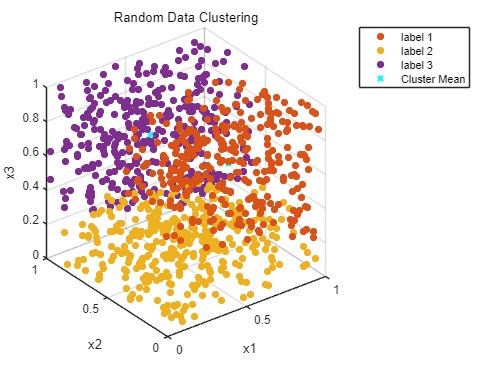

% Labeling the clusters
for i = 1:K
    scatter3(X(C_num ==i,1), X(C_num ==i,2), X(C_num ==i,3), 'filled'); 
end

scatter3(C_mean(:,1),C_mean(:,2),C_mean(:,3),'cx','LineWidth',2)
legend('','label 1', 'label 2', 'label 3', 'Cluster Mean');